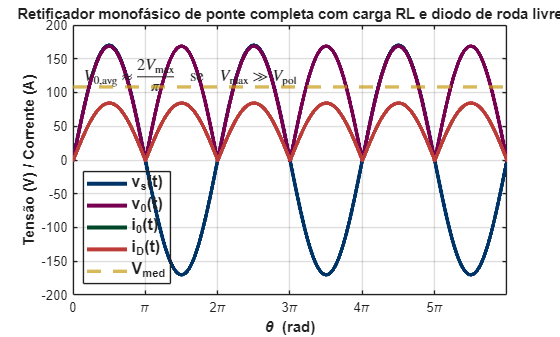

%% Retificador monofásico de ponte completa + carga RL + diodo de roda livre (Df)

clear; clc; close all;

f   = 60;
Vm  = 170;
R   = 2;
L   = 5e-5;
Vd  = 0.7;
Vdf = 0.7;
ncy = 30;
fs  = 200e3;

T  = 1/f;
dt = 1/fs;
t  = 0:dt:(ncy*T);
N  = numel(t);

omega = 2*pi*f;
theta = omega*t;
v_s   = Vm*sin(theta);

i_0 = zeros(1,N);
v_0 = zeros(1,N);
i_D = zeros(1,N);

for k = 2:N
    i_prev = i_0(k-1);

    vrec = abs(v_s(k)) - 2*Vd;
    if vrec < 0
        vrec = 0;
    end

    if (vrec > -Vdf) && (vrec > 0)
        v_0(k) = vrec;

        di   = (v_0(k) - R*i_prev)/L;
        iNew = i_prev + di*dt;

        if iNew < 0, iNew = 0; end
        i_0(k) = iNew;
        i_D(k) = iNew;

        if i_0(k) == 0
            v_0(k) = 0;
            i_D(k) = 0;
        end

    elseif i_prev > 0
        v_0(k) = -Vdf;

        di   = (v_0(k) - R*i_prev)/L;
        iNew = i_prev + di*dt;

        if iNew < 0, iNew = 0; end
        i_0(k) = iNew;
        i_D(k) = 0;

        if i_0(k) == 0
            v_0(k) = 0;
        end

    else
        v_0(k) = 0;
        i_0(k) = 0;
        i_D(k) = 0;
    end
end

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;

plotColors = [
    statale.maincolor
    statale.lilla
    statale.darkgreen
    statale.red
    statale.yellow
];
set(groot,'defaultAxesColorOrder',plotColors);

LW = 3.0;

plotCycles = [10 12];
c1 = plotCycles(1);
c2 = plotCycles(2);

t1 = (c1-1)*T;
t2 = c2*T;

idx = (t >= t1) & (t <= t2);

thetaP = theta(idx);
vsP    = v_s(idx);
v0P    = v_0(idx);
i0P    = i_0(idx);
iDP    = i_D(idx);

thetaRel = thetaP - thetaP(1);

figure('Color','w');
plot(thetaRel, vsP, 'Color', plotColors(1,:), 'LineWidth', LW); hold on;
plot(thetaRel, v0P, 'Color', plotColors(2,:), 'LineWidth', LW);
plot(thetaRel, i0P, 'Color', plotColors(3,:), 'LineWidth', LW);
plot(thetaRel, iDP, 'Color', plotColors(4,:), 'LineWidth', LW);
grid on;

xlabel('\theta (rad)');
ylabel('Tensão (V) / Corrente (A)');
title('Retificador monofásico de ponte completa com carga RL e diodo de roda livre');

xlim([0, thetaRel(end)]);
k2 = floor(thetaRel(end)/pi);
xt = (0:k2)*pi;
xticks(xt);

m = 0:k2;
labs = strings(size(m));
for kk = 1:numel(m)
    if m(kk) == 0
        labs(kk) = "0";
    elseif m(kk) == 1
        labs(kk) = "\pi";
    else
        labs(kk) = sprintf('%g\\pi', m(kk));
    end
end
xticklabels(labs);

Vmax = Vm;
Vpol = 2*Vd;

Vavg_approx = 2*Vmax/pi;

hAvg = yline(Vavg_approx, '--', 'LineWidth', 2.5);
hAvg.Color = plotColors(5,:);

txt = '$V_{0,\mathrm{avg}} \approx \frac{2V_{\max}}{\pi}\ \ \mathrm{se}\ \ V_{\max} \gg V_{\mathrm{pol}}$';
text(0.02*thetaRel(end), 0.92*max(v0P), txt, ...
    'Interpreter','latex', 'FontWeight','bold', 'FontSize', 12, ...
    'VerticalAlignment','top');

lgd = legend('v_s(t)','v_0(t)','i_0(t)','i_D(t)','V_{med}','Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';